## a)

years = [1960 1970 1980 1990 2000 2010];
population = [179323 203302 226542 249663 281422 308746];

estimation_years = [1950 1985 2030];

estimation_polylagrange = zeros(1, 3);
estimation_polynewton = zeros(1, 3);

for i = 1:3
    [~, val] = polylagrange(years, population, estimation_years(i));
    estimation_polylagrange(i) = val;
    [~, val] = polynewton(years, population, estimation_years(i));
    estimation_polynewton(i) = val;
end

disp('Matriz de estimaciones:');

Matriz de estimaciones:


disp(estimation_polylagrange);

   1.0e+05 *

    1.9209    2.3741    0.0884



disp(estimation_polynewton);

   1.0e+05 *

    1.9209    2.3741    0.0885



## b)

El fenómeno de Runge fue descubierto por Carl David Tolmé Runge cuando exploraba el comportamiento de los errores al usar interpolación polinómica para aproximar determinadas funciones por polinomios de alto grado utilizando nodos equidistantes. En este caso se garantiza que el error máximo se incrementa al aumentar el orden polinómico.

a = 0;
b = 8*pi;
f = @(x) cos(x);
N = 1:10;

x_val = linspace(a, b, 1000);
f_val = f(x_val);

max_error_lagrange = zeros(size(N));
max_error_newton = zeros(size(N));

for n = N
    x = linspace(a, b, n+1);
    y = f(x);
    lagrange_val = zeros(size(x_val));
    newton_val = zeros(size(x_val));
    for i = 1:length(x_val)
        [~, val] = polylagrange(x, y, x_val(i));
        lagrange_val(i) = val;

        [~, val] = polynewton(x, y, x_val(i));
        newton_val(i) = val;
    end

    max_error_lagrange(n) = max(abs(f_val - lagrange_val));
    max_error_newton(n) = max(abs(f_val - newton_val));

end

plot(N, max_error_lagrange, 'ro');

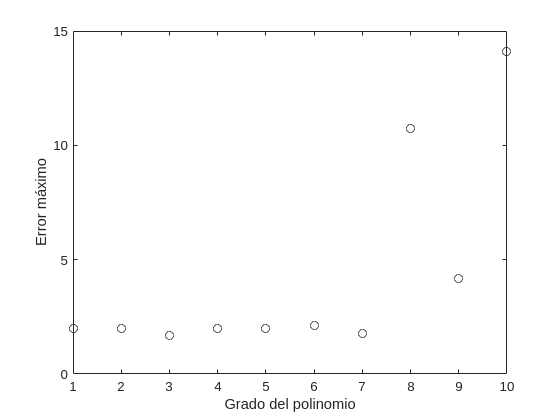

hold on
plot(N, max_error_newton, 'ko');
xlabel('Grado del polinomio');
ylabel('Error máximo');
hold off

## c)

t = [50 60 70 80 90 100];
p = [24.94 30.11 36.05 42.84 50.57 59.30];

[dd, val] = polynewton(t, p, 64);
disp(dd);

   24.9400    0.5170    0.0038    0.0000    0.0000   -0.0000
   30.1100    0.5940    0.0043    0.0000   -0.0000         0
   36.0500    0.6790    0.0047    0.0000         0         0
   42.8400    0.7730    0.0050         0         0         0
   50.5700    0.8730         0         0         0         0
   59.3000         0         0         0         0         0



disp(val);

   32.3898



## d)

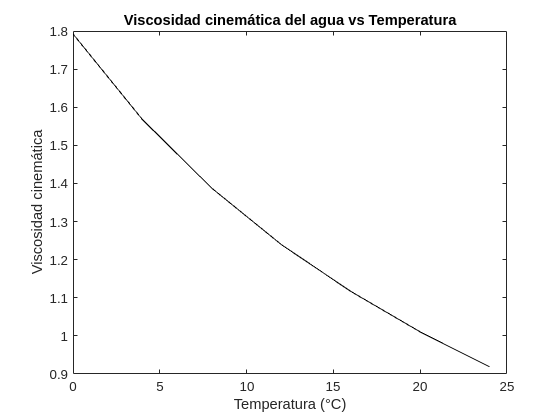

t = [0 4 8 12 16 20 24];
v = [1.7923 1.5676 1.3874 1.2396 1.1168 1.0105 0.9186];

plot(t, v, 'k');
xlabel('Temperatura (°C)');
ylabel('Viscosidad cinemática');
title('Viscosidad cinemática del agua vs Temperatura');

line = polyfit(t, v, 1);
prediction = polyval(line, 7.5);
display(prediction);

prediction = 1.4514

line = polyfit(t, v, 2);
prediction = polyval(line, 7.5);
display(prediction);

prediction = 1.4161

## e)

x = [4.0 4.2 4.5 4.7 5.1 5.5 5.9 6.3 6.8 7.1];
y = [102.56 113.18 130.11 142.05 167.53 195.14 224.87 256.73 299.50 326.72];

disp('Polinomio de primer grado:');

Polinomio de primer grado:


line = polyfit(x, y, 1);
y1 = polyval(line, x);
e = sum((y - y1).^2);
disp('Error:');

Error:


disp(e);

  329.0132



disp('Polinomio de segundo grado:');

Polinomio de segundo grado:


line = polyfit(x, y, 2);
y1 = polyval(line, x);
e = sum((y - y1).^2);
disp('Error:');

Error:


disp(e);

    0.0014



disp('Polinomio de tercer grado:');

Polinomio de tercer grado:


line = polyfit(x, y, 3);
y1 = polyval(line, x);
e = sum((y - y1).^2);
disp('Error:');

Error:


disp(e);

   5.2734e-04



disp('Aproximación de mínimos cuadrados de la forma exponencial:');

Aproximación de mínimos cuadrados de la forma exponencial:


line = polyfit(x, log(y), 3);
a = line(1);
B = line(2);
b = exp(B);
func = b * exp(a*x);
e = sum((y - func).^2);
disp('Error:');

Error:


disp(e);

   4.3590e+05

